# **Project 2 - Effectivness of Not Switching Classrooms**

**By Michaela Fox and Elisa Camacho**

## **Question**

Our modeling question is does having students stay in one classroom reduce the number of students that get the common cold as opposed to having students switch classrooms like in most schools? This is a prediction question, because we are trying to predict if a certain way of arranging students will better protect against the common cold. This is interesting because it will help us find a new way of stopping the spread of a disease like the common cold in the school setting. Our model's results will benefit people who work in school districts such as teachers who interact directly with the high schoolers, principals, and the high schooler's family.

## **One Classroom Model **

Our first model shows these 7 pods with 20 nodes in each, this represents 7 classrooms with 20 students in each of them. All the nodes in each pod are connected to eachother modeling how every kid in the classroom will interact in one way or another with every one of their classmates. We assume each connection between the nodes are the same. This model visually shows if we used the podding method to decrease the spread of a disease, that disease would only be contained within that pod and not spread to the other pods. 

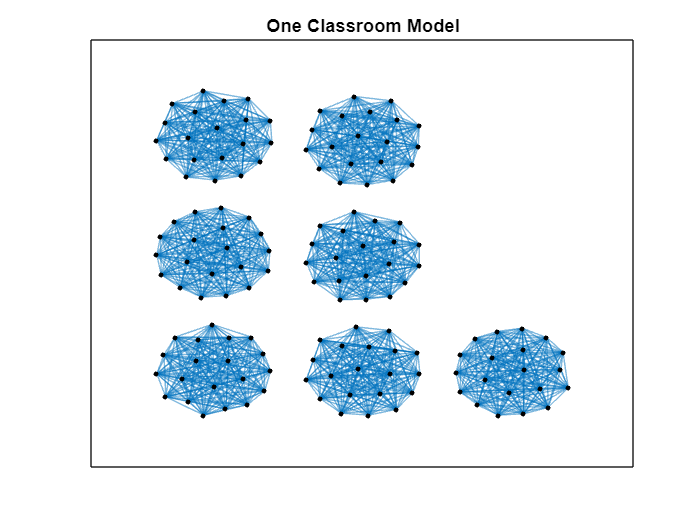

pod20 = ones(20,20) - eye(20);
zeros20 = zeros(20,20);
finalmatrix = [
    pod20 zeros20 zeros20 zeros20 zeros20 zeros20 zeros20;
    zeros20 pod20 zeros20 zeros20 zeros20 zeros20 zeros20;
    zeros20 zeros20 pod20 zeros20 zeros20 zeros20 zeros20;
    zeros20 zeros20 zeros20 pod20 zeros20 zeros20 zeros20;
    zeros20 zeros20 zeros20 zeros20 pod20 zeros20 zeros20;
    zeros20 zeros20 zeros20 zeros20 zeros20 pod20 zeros20;
    zeros20 zeros20 zeros20 zeros20 zeros20 zeros20 pod20]
graph20pod = graph(finalmatrix);
figure();
h = plot(graph20pod, 'NodeColor', 'k', 'LineWidth', 0.1);
layout(h, 'force', 'WeightEffect', 'inverse')
title('One Classroom Model')

## **Switched Classroom Model **

This model shows the connections between students if they switched classrooms for every class with a new set of students in each class. Their are many more connections between the nodes. 

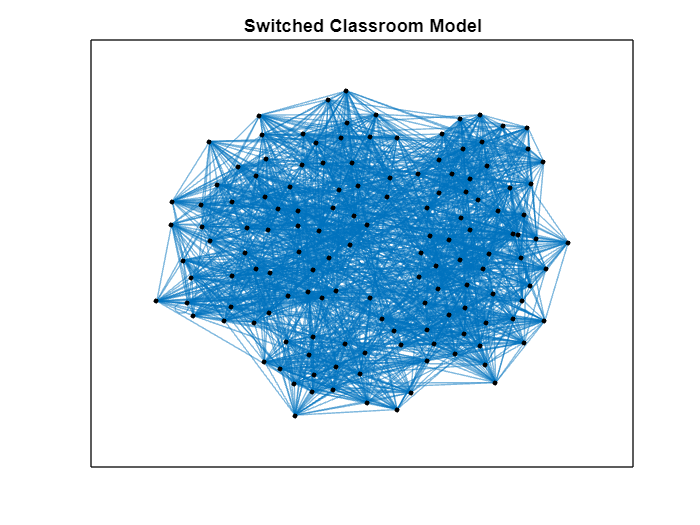

finalmatrix2 = finalmatrix;
rng(0,'twister');
for i = 1:980
    p1 = randi([1 140]);
    p2 = randi([1 140]);
    finalmatrix2(p1,p2) = finalmatrix2(p1,p2) + 1;
    finalmatrix2(p2,p1) = finalmatrix2(p2,p1) + 1;
end
graph20pod2 = graph(finalmatrix2);
figure();
h = plot(graph20pod2, 'NodeColor', 'k', 'LineWidth', 0.1);
layout(h, 'force', 'WeightEffect', 'inverse')
title('Switched Classroom Model')

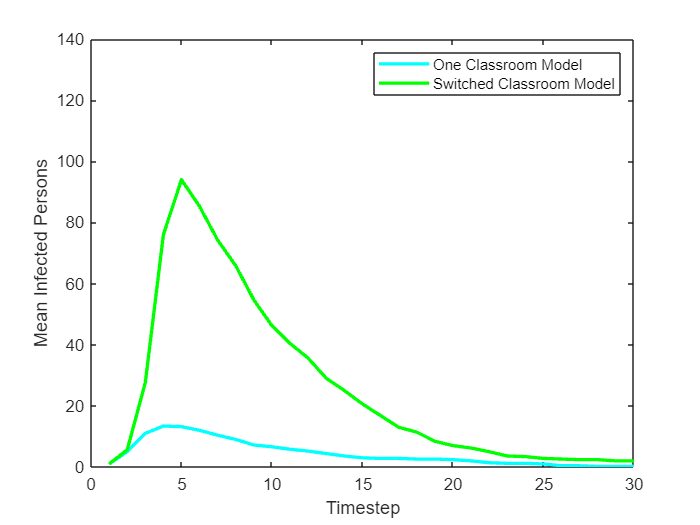

%Simulate one classroom model
infectionrate = 0.324;
recoveryrate = 0.143;
iv0 = zeros(140,1);
iv0(1) = 1;
timesteps = 30;
realizations = 5;
simresults1 = zeros(timesteps, realizations);
simresults2 = zeros(timesteps, realizations);
for i = 1:realizations
    [sho,iho,rho] =  simulate_absir(finalmatrix, iv0, timesteps, infectionrate, recoveryrate);
    simresults1(:, i) = sum(iho, 1);
end
%Simulate switched classroom model
for s = 1:realizations
    [shs,ihs,rhs] =  simulate_absir(finalmatrix2, iv0, timesteps, infectionrate, recoveryrate);
    simresults2(:,s) = sum(ihs,1);
end
meano = mean(simresults1, 2);
means = mean(simresults2, 2);
%icounto = sum(iho,1);
%icounts = sum(ihs,1);
figure()
plot(meano, 'c-', 'LineWidth', 2.0, 'DisplayName', 'One Classroom Model');
xlabel('Timestep')
ylabel('Mean Infected Persons')
ylim([0 140])
legend() 
hold on;
plot(means, 'g-', 'LineWidth', 2.0, 'DisplayName', 'Switched Classroom Model');

## **Results**

This graph shows the difference mean of infection with the one classroom model and the switched classroom model over 30 days. This simulation proves that our switched classroom method was successful in lowering the mean infection flow. We found in our research that the infection rate of the common cold is 0.324 and the recovery rate is 0.143. This rate presents how cold viruses spread through respiratory droplets when infected individuals cough or sneeze, making others susceptible then infected. 

## **Interpretation **

Our results show that keeping students in one classroom all day decreases the rate of infection, this means our prediction that using the podding/one classroom method worked in decreasing and stopping the spread of the common cold in school. This information can be used for the future pandemics to help decrease the spread in schools by implementing this method of podding/one classroom method. 